A  Explore the data and comment on your findings.

clc, clf, clear

craneA = [140 140 112 90 32 154 359 207 61 39 40];
craneB = [69 14 38 94 46 36 84 106 269 445 42 108 244 92 148 303 24 328 207 260 132 56];
craneC = [39 135 57 31 190 90 293 151 26 77 82 156 328 92 138 47 45];

% Calculate number of samples
nA = length(craneA);
nB = length(craneB);
nC = length(craneC);

% Calculate mean of samples
avgA = mean(craneA);
avgB = mean(craneB);
avgC = mean(craneC);

% Calculate median of samples
mA = median(craneA);
mB = median(craneB);
mC = median(craneC);

% Calculate minimum of samples
minA = min(craneA);
minB = min(craneB);
minC = min(craneC);

% Calculate maximum of samples
maxA = max(craneA);
maxB = max(craneB);
maxC = max(craneC);

% Calculate range of samples
rA = maxA - minA;
rB = maxB - minB;
rC = maxC - minC;

% Calculate variance of samples
varA = var(craneA);
varB = var(craneB);
varC = var(craneC);

% Calculate standard deviation of samples
stdA = std(craneA);
stdB = std(craneB);
stdC = std(craneC);

% Calculate IQR
iqrA = iqr(craneA);
iqrB = iqr(craneB);
iqrC = iqr(craneC);

% Calculate outlier
outliersA = craneA(craneA > (avgA + 1.5 * stdA) | craneA < (avgA - 1.5 * stdA));
outliersB = craneB(craneB > (avgB + 1.5 * stdB) | craneB < (avgB - 1.5 * stdB));
outliersC = craneC(craneC > (avgC + 1.5 * stdC) | craneC < (avgC - 1.5 * stdC));

% Display results as table
names = {'Crane 14'; 'Crane 15'; 'Crane 16'};
n = [nA; nB; nC];
mean = [avgA; avgB; avgC];
median = [mA; mB; mC];
min = [minA; minB; minC];
max = [maxA; maxB; maxC];
range = [rA; rB; rC];
variance = [varA; varB; varC];
std = [stdA; stdB; stdC];
IQR = [iqrA; iqrB; iqrC];
outliers = {outliersA; outliersB; outliersC};

T = table(n, mean, median, min, max, range, variance, std, IQR, outliers, ...
    'RowNames', names);

% Display table title
disp("Summary Statistics for Cranes")

Summary Statistics for Cranes


disp(T)

                n      mean     median    min    max    range    variance     std       IQR       outliers  
                __    ______    ______    ___    ___    _____    ________    ______    ______    ___________

    Crane 14    11    124.91     112      32     359     327      9153.1     95.672    105.25    {[    359]}
    Crane 15    22    142.95     100      14     445     431       13907     117.93       198    {[445 328]}
    Crane 16    17    116.29      90      26     328     302      7742.7     87.993    105.75    {[293 328]}



初步分析：

Plot the graph 

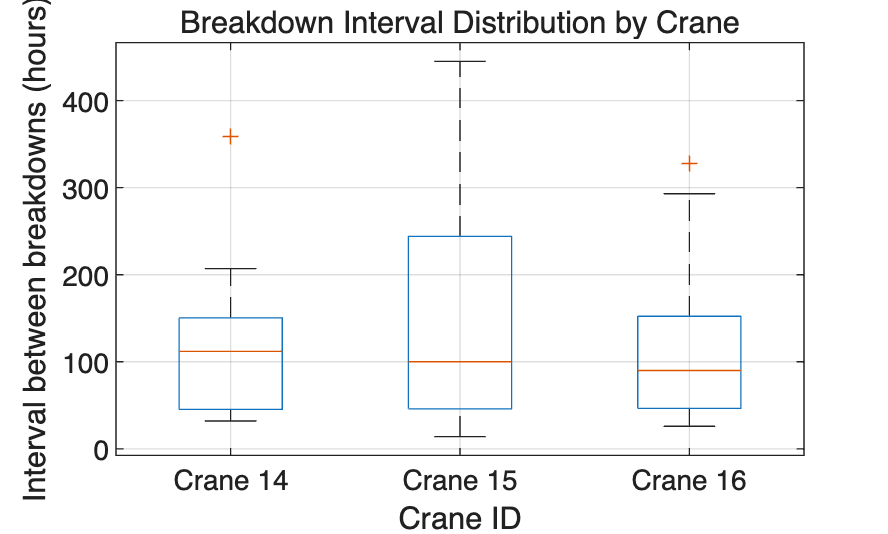

%% Combine data
all_data = [craneA'; craneB'; craneC'];
group_labels = [repmat({'Crane 14'}, length(craneA), 1);
           repmat({'Crane 15'}, length(craneB), 1);
           repmat({'Crane 16'}, length(craneC), 1)];

%% Create grouped box plot
figure;
boxplot(all_data, group_labels,'Labels', {'Crane 14', 'Crane 15', 'Crane 16'});
xlabel('Crane ID')
ylabel('Interval between breakdowns (hours)')
title('Breakdown Interval Distribution by Crane')
grid on;

直方图

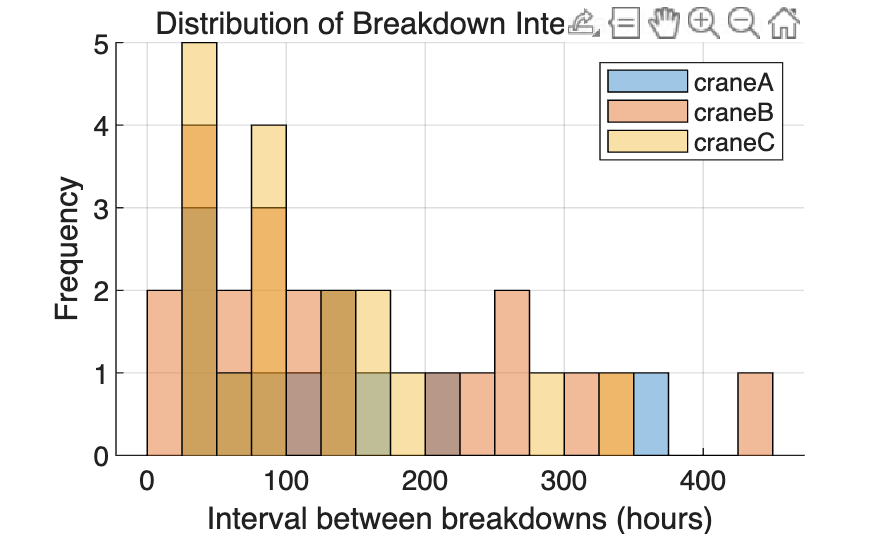

% === 设置基础参数 ===
figure; 
hold on;
colors = lines(3);           % 三组默认颜色
bin_width = 25;              % 直方图区间宽度
cranes = {craneA, craneB, craneC};
names  = {'Crane 14', 'Crane 15', 'Crane 16'};

hA = histogram(craneA, 'BinWidth', bin_width, 'FaceColor', colors(1,:), 'EdgeColor', 'k', 'FaceAlpha', 0.4);
% [fA, xA] = ksdensity(craneA); % 核密度估计
% plot(xA, fA * sum(hA.Values) * hA.BinWidth, 'Color', colors(1,:), 'LineWidth', 2); % 缩放 KDE 以匹配直方图的尺度

% 绘制 Crane B 的直方图和 KDE
hB = histogram(craneB, 'BinWidth', bin_width, 'FaceColor', colors(2,:), 'EdgeColor', 'k', 'FaceAlpha', 0.4);
% [fB, xB] = ksdensity(craneB);
% plot(xB, fB * sum(hB.Values) * hB.BinWidth, 'Color', colors(2,:), 'LineWidth', 2);

% 绘制 Crane C 的直方图和 KDE
hC = histogram(craneC, 'BinWidth', bin_width, 'FaceColor', colors(3,:), 'EdgeColor', 'k', 'FaceAlpha', 0.4);
% [fC, xC] = ksdensity(craneC);
% plot(xC, fC * sum(hC.Values) * hC.BinWidth, 'Color', colors(3,:), 'LineWidth', 2);
title('Distribution of Breakdown Intervals by Crane');
xlabel('Interval between breakdowns (hours)');
ylabel('Frequency');
legend('Location', 'NorthEast');
grid on;
hold off;